# Práctica 01 - Introducción al software de cálculo

#### Autor: Reyes Iglesias Bruno Fernando

**Instrucción:** *Los estudiantes usarán Matlab y Python para desarrollar los siguientes ejercicios. Se enfocarán en comprender el flujo de programación y visualización de resultados.*

**1.** Calcular el volumen molar que ocupa un gas:

        **a.** En condiciones normales

        **b.** En condiciones estándar

        **c.** T = 1000 ºC y P = 1 atm

**    SOLUCIÓN:**

    Usando la ecuación de los gases ideales:

                                
$$\textrm{PV}=\textrm{nRT}$$


        $P$: Presión en $\textrm{atm}$

        $V$: Volumen en $\mathrm{L}$

        $n$: Número de moles

        $R$: Constante de los gases ideales $0\ldotp 0821\;\textrm{atm}\;\mathrm{L}\;{\textrm{mol}}^{-1} \;{\mathrm{K}}^{-1}$

        $T$: Temperatura $\mathrm{K}$

    Se tiene que el volumen molar: $V_m =V/n$

    Despejando: $V_m =\frac{\textrm{RT}}{P}$, entonces:

        **a.** En condiciones normales (T = 25 ºC y P = 1 atm)

%% PROBLEMA 1
% a. Condiciones normales (25 C, 1 atm)
P  = 1; % atm
T  = 25+273.15; % K
R  = 0.08205746; % atm.L/mol.K
Vm = R.*T./P; % L/mol
fprintf('Presion = %1.2g atm \n',P)

Presion = 1 atm 


fprintf('Temperatura = %1.6g K \n',T)

Temperatura = 298.15 K 


fprintf('Volumen Molar = %1.6g L/mol \n',Vm)

Volumen Molar = 24.4654 L/mol 


        **b.** En condiciones estándar (T = 0 ºC y P = 1 atm)

% b. Condiciones estandar (0 C, 1 atm)
P  = 1; % atm
T  = 273.15; % K
R  = 0.08205746; % atm.L/mol.K
Vm = R.*T./P; % L/mol
fprintf('Presion = %1.2g atm \n',P)

Presion = 1 atm 


fprintf('Temperatura = %1.6g K \n',T)

Temperatura = 273.15 K 


fprintf('Volumen Molar = %1.6g L/mol \n',Vm)

Volumen Molar = 22.414 L/mol 


        **c.** T = 1000 ºC y P = 1 atm

% c. Condiciones (1000 C, 1 atm)
P  = 1; % atm
T  = 1000+273.15; % K
R  = 0.08205746; % atm.L/mol.K
Vm = R.*T./P; % L/mol
fprintf('Presion = %1.2g atm \n',P)

Presion = 1 atm 


fprintf('Temperatura = %1.6g K \n',T)

Temperatura = 1273.15 K 


fprintf('Volumen Molar = %1.6g L/mol \n',Vm)

Volumen Molar = 104.471 L/mol 


**2.** El monitor de una estación de control de la contaminación atmosférica da una concentración diaria promedio para el ${\textrm{SO}}_2$ de $480\;\mu g/m^3$ a $30\;\textrm{ºC}$ y $1\;\textrm{atm}$. ¿Cuál será la concentración de ${\textrm{SO}}_2$ en ppm? Dato: Pesos atómicos S = 32, O = 16.

**    SOLUCIÓN:**

        Partes por millón (ppm):

                
$$\textrm{ppm}=\frac{\textrm{unidades}\;\textrm{de}\;\textrm{soluto}}{\textrm{unidades}\;\textrm{de}\;\textrm{solución}}\times {10}^6$$


                
$$\mathrm{ppm}\cong \frac{\mathrm{mg}\;\mathrm{de}\;\mathrm{soluto}}{\mathrm{kg}\;\mathrm{de}\;\mathrm{solución}}\cong \frac{\mathrm{mg}\;\mathrm{de}\;\mathrm{soluto}}{\mathrm{L}\;\mathrm{de}\;\mathrm{solución}}\cong \frac{\mathrm{mL}\;\mathrm{de}\;\mathrm{soluto}}{\mathrm{kg}\;\mathrm{de}\;\mathrm{solución}}\cong \frac{\mathrm{mL}\;\mathrm{de}\;\mathrm{soluto}}{m^3 \;\mathrm{de}\;\mathrm{solución}}$$


        **NOTA:** Se puede convertir entre las diferentes unidades que representan ppm siempre que se se trate con soluciones de densidad 1.

        Se calcula el peso molecular del ${\textrm{SO}}_2$ a partir de los datos:

%% PROBLEMA 2
% Peso molecular del SO2
PM_S = 32; % g/mol
PM_O = 16; % g/mol
PM_SO2 = PM_S+2.*PM_O; % g/mol
fprintf('Peso molecular del SO2 = %1.6g g/mol \n',PM_SO2)

Peso molecular del SO2 = 64 g/mol 


        Las unidades de concentración diaria promedio están en $\mu g/m^3$, se convierte a $g/L$ para poder operar:

                    
$$480\;\frac{\mu g}{m^{3\;} }\left(\frac{{10}^{-6} \;g}{1\;\mu g}\right)\left(\frac{m^3 }{{10}^{3\;} \;L}\right)$$


% Concentracion del SO2
Conc_SO2 = 480; % ug/m^3
Conc_SO2 = Conc_SO2.*(10^-6)./(10.^3); % g/L
fprintf('Concentracion de SO2 = %1.6g g/L\n',Conc_SO2)

Concentracion de SO2 = 4.8e-07 g/L


        Se toma una base de cálculo con respecto al aire, en este caso será 1 L de aire.

        Luego se halla el número de moles de ${\textrm{SO}}_2$ presentes en 1 L de aire a partir de la concentración dada:

                    
$$n_{{\textrm{SO}}_2 } =\frac{\left\lbrack {\textrm{SO}}_2 \right\rbrack \times 1\;L}{{\textrm{PM}}_{{\textrm{SO}}_2 } }=\frac{4\ldotp 8\times {10}^{-7} \;g}{96\;g/\textrm{mol}}$$


% Moles de SO2
V_air = 1; % L
n_SO2 = Conc_SO2.*V_air./PM_SO2; % mol
fprintf('Moles de SO2 = %1.6g mol',n_SO2)

Moles de SO2 = 7.5e-09 mol

        Se halla el volumen de ${\textrm{SO}}_2$ a las condiciones dadas (30 ºC y 1 atm) usando la ecuación de gases ideales:

% Volumen de SO2
P = 1; % atm
T = 30+273.15; % K
R = 0.08205746; % atm.L/mol.K
V_SO2 = n_SO2.*R.*T./P; % L
fprintf('Volumen de SO2 = %1.6g L \n',V_SO2)

Volumen de SO2 = 1.86568e-07 L 


        Se halla las ppm de ${\textrm{SO}}_2$ por fórmula:

                    
$${\mathrm{ppm}}_{{\mathrm{SO}}_2 } =\frac{V_{{\mathrm{SO}}_2 } }{1\;L\;\mathrm{aire}}\times {10}^6$$


% ppm de SO2
ppm_SO2 = V_SO2./V_air.*10.^6;
fprintf('ppm de SO2 = %1.6g \n',ppm_SO2)

ppm de SO2 = 0.186568 


**3.** Se observa que la concentración diaria promedio para el $\textrm{NO}$ en una estación es de $40\;\mu g/m^3$ a $25\;\textrm{ºC}$ y $750\;\textrm{mm}$ de presión. ¿Cuál será la concentración de $\textrm{NO}$ en ppm? Dato: Pesos atómicos N = 14, O = 16.

**    SOLUCIÓN:**

        Se desarrolla de forma similar al inciso 2, cambiando la constante de gases ideales $\mathrm{R}=62\ldotp 36367\;\mathrm{L}\;\textrm{mmHg}\;{\textrm{mol}}^{-1} \;{\mathrm{K}}^{-1}$.

%% PROBLEMA 3
% Peso molecular del NO
PM_N = 14; % g/mol
PM_O = 16; % g/mol
PM_NO = PM_N+PM_O; % g/mol
fprintf('Peso molecular del NO = %1.6g g/mol \n',PM_NO)

Peso molecular del NO = 30 g/mol 


% Concentracion del NO
Conc_NO = 40; % ug/m^3
Conc_NO = Conc_NO.*(10^-6)./(10.^3); % g/L
fprintf('Concentracion de NO = %1.6g g/L\n',Conc_NO)

Concentracion de NO = 4e-08 g/L


% Moles de NO
V_air = 1; % L
n_NO = Conc_NO.*V_air./PM_NO; % mol
fprintf('Moles de NO = %1.6g mol',n_NO)

Moles de NO = 1.33333e-09 mol

% Volumen de NO
P = 750; % mmHg
T = 25+273.15; % K
R = 62.36367; % L.mmHg/mol.K
V_NO = n_NO.*R.*T./P; % L
fprintf('Volumen de NO = %1.6g L \n',V_NO)

Volumen de NO = 3.30555e-08 L 


% ppm de NO
ppm_NO = V_NO./V_air.*10.^6;
fprintf('ppm de NO = %1.6g \n',ppm_NO)

ppm de NO = 0.0330555 


**4.** Un laboratorio que tiene las siguientes dimensiones 10 m de largo por 5 m de ancho y 3 m de altura, tiene en su interior 7 botellas de nitrógeno de 25 L de capacidad a una presión de 200 atm. Debido a una fuga en el sistema de interconexión de las botellas, éstas se vacían completamente.

Calcular el % de ${\mathrm{O}}_2$ en el ambiente del laboratorio tras la fuga y verificar si dicho valor supone riesgo para la salud, sabiendo que el Valor Límite Umbral para el ${\mathrm{O}}_2$ es del 18 % en volumen.

Considerar que el laboratorio se encuentra a una presión de 1 atm y a 25 ºC de temperatura.

**    SOLUCIÓN:**

        Se supone una habitación rectangular aislada en la que se encuentran aire y las 7 botellas de nitrógeno, se despreciará el volumen que ocupa las botellas vacías. Entonces se tiene como sistema algo parecido a la siguiente imagen:

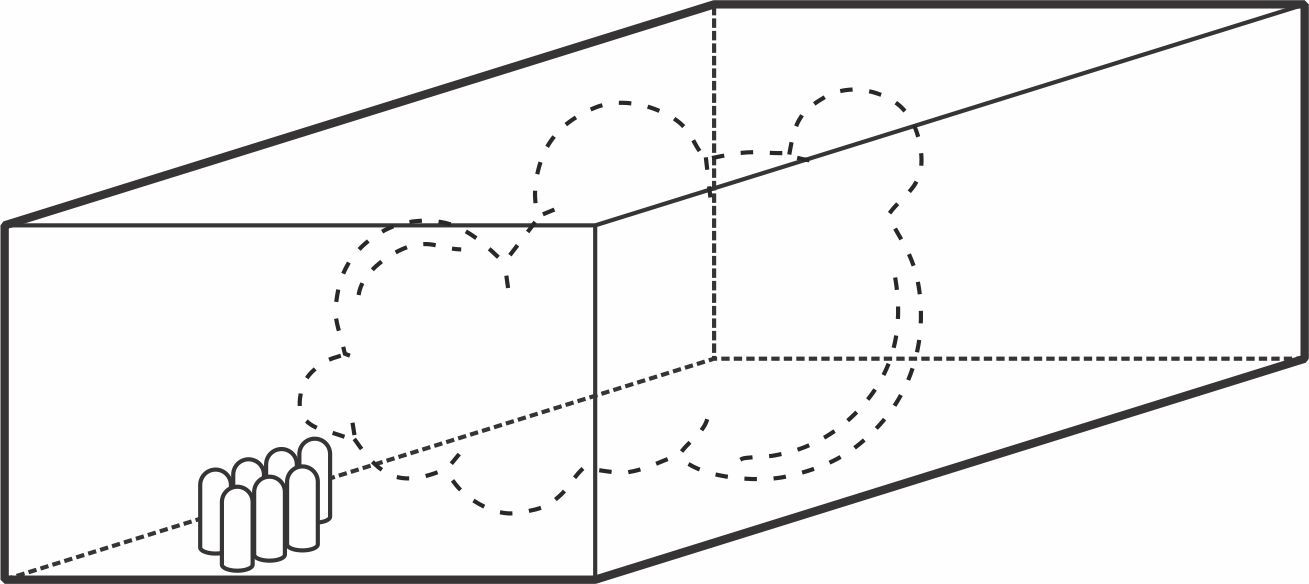

        Primero se halla el volumen de la habitación que estaría ocupado por aire antes de la fuga, que sería igual al volumen total del laboratorio menos el volumen del nitrógeno en botellas:

                    
$$V_{\mathrm{lab}} =\mathrm{Ancho}\times \mathrm{Largo}\times \mathrm{Altura}=5\;m\times 10\;m\times 3\;m$$


                    
$$V_{N_2 } =7\times 25\;L$$


                    
$$V_{\mathrm{air}} =V_{\mathrm{lab}} -V_{N_2 }$$


%% PROBLEMA 4
% Volumen del aire en el laboratorio
A = 5; % m
L = 10; % m
H = 3; % m
V_N2_bot = 7.*25; % L
V_lab = A.*L.*H; % m^3
V_air = V_lab.*(10.^3)-V_N2_bot; % L
fprintf('Volumen del aire en el laboratorio = %1.6g L \n',V_air)

Volumen del aire en el laboratorio = 149825 L 


        Se sabe que la composición del aire es aproximadamente 21 % ${\mathrm{O}}_2$ y 79 % ${\mathrm{N}}_2$.

        Se halla el número de moles de nitrógeno y oxígeno en el aire del laboratorio, y los moles del nitrógeno en las botellas, de acuerdo a los datos:

                    Oxígeno en laboratorio: $V_{O_2 } =21%\left(V_{\mathrm{air}} \right)$         $n_{O_2 } =\frac{P_{\mathrm{lab}} V_{O_2 } }{\mathrm{RT}}$

                    Nitrógeno en laboratorio: $V_{N_2 \left(\mathrm{lab}\right)} =79%\left(V_{\mathrm{air}} \right)$         $n_{N_2 \left(\mathrm{lab}\right)} =\frac{P_{\mathrm{lab}} V_{N_2 \left(\mathrm{lab}\right)} }{\mathrm{RT}}$

                    Nitrógeno en botellas: $V_{N_2 \left(\mathrm{bot}\right)} =7\left(25\;L\right)$         $n_{N_2 \left(\mathrm{bot}\right)} =\frac{P_{\mathrm{bot}} V_{N_2 \left(\mathrm{bot}\right)} }{\mathrm{RT}}$

% Composicion del aire en laboratorio
% Condiciones
P_lab = 1; % atm
P_bot = 200; % atm
T = 25+273.15; % K
R = 0.08205746; % atm.L/mol.K
V_O2 = 0.21.*V_air; % L
fprintf('Volumen de O2 en laboratorio = %1.6g L \n',V_O2)

Volumen de O2 en laboratorio = 31463.2 L 


V_N2_lab = 0.79.*V_air; % L
fprintf('Volumen de N2 en laboratorio = %1.6g L \n',V_N2_lab)

Volumen de N2 en laboratorio = 118362 L 


fprintf('Volumen de N2 en botellas = %1.6g L \n',V_N2_bot)

Volumen de N2 en botellas = 175 L 


n_O2 = P_lab.*V_O2./(R.*T); % mol
fprintf('Moles de O2 en laboratorio = %1.6g mol \n',n_O2)

Moles de O2 en laboratorio = 1286.03 mol 


n_N2_lab = P_lab.*V_N2_lab./(R.*T); % mol
fprintf('Moles de N2 en laboratorio = %1.6g mol \n',n_N2_lab)

Moles de N2 en laboratorio = 4837.92 mol 


n_N2_bot = P_bot.*V_N2_bot./(R.*T); % mol
fprintf('Moles de N2 en botellas = %1.6g mol \n',n_N2_bot)

Moles de N2 en botellas = 1430.59 mol 


        Se determina la composición de oxígeno luego de la fuga, teniendo en cuenta los moles de ${\mathrm{N}}_2$ de las botellas:

        También se tiene en cuenta que como se está trabajando con gases el porcentaje debería darse en %vol, sin embargo, ya que se trabaja con idealidad se puede asumir que el porcentaje molar es idéntico al %vol debido a que en la ecuación de gases el volumen y los moles son directamente proporcionales.

                    
$$\mathrm{Moles}\;\mathrm{totales}=n_{O_2 } +n_{N_2 \left(\mathrm{lab}\right)} +n_{N_2 \left(\mathrm{bot}\right)}$$


                    $%O_2 =\frac{n_{O_2 } }{\mathrm{Moles}\;\mathrm{totales}}\times 100\;%$                Si: $%O_2 <18%$ hay peligro

% Porcentaje de O2 luego de la fuga
n_tot = n_O2+n_N2_lab+n_N2_bot; % mol
Conc_O2 = n_O2./n_tot.*100; % %
fprintf('Concentracion de O2 = %1.6g %% \n',Conc_O2)

Concentracion de O2 = 17.0233 % 


if any(Conc_O2 < 18)
    fprintf('///// ALERTA ///// NIVEL DE O2 BAJO - RIESGO PARA LA SALUD \n')
else
    fprintf('NIVEL DE O2 NORMAL \n')
end

///// ALERTA /////  NIVEL DE O2 BAJO - RIESGO PARA LA SALUD 
